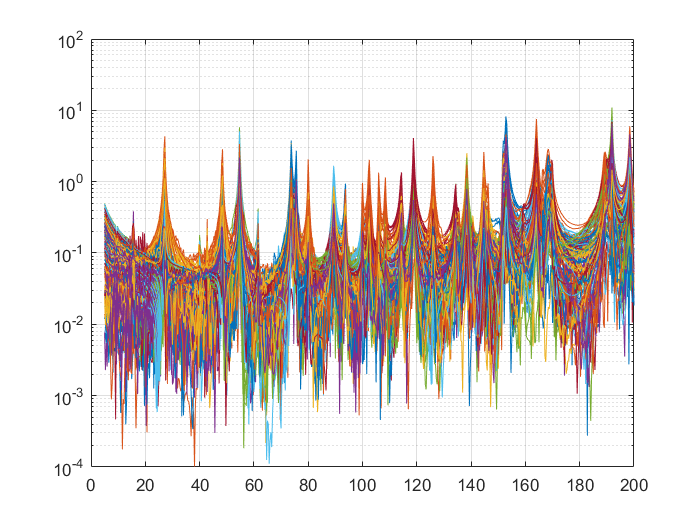


clear
clc

load VehicleStructures_Freq.mat

A=Measurements.measData ;
B=Measurements.freq ;

semilogy (B,abs(A))
grid on


semilogy (B,abs(A(:,30)))
hold

Current plot held


semilogy (B,abs(A(:,40)))
semilogy (B,abs(A(:,60)))
semilogy (B,abs(A(:,80)))
semilogy (B,abs(A(:,100)))
grid on

%Focus on the first mode

freqs=B(61:85) ;
amps=A(61:85,30) ;


semilogy (freqs,abs(amps))
hold

Current plot released


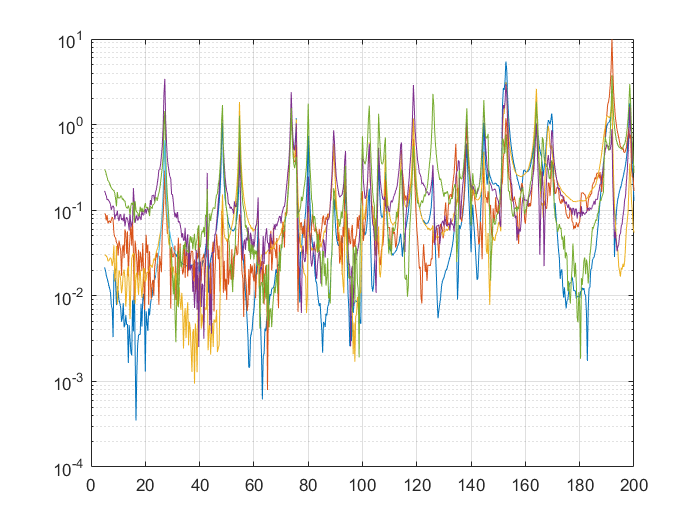

grid on


%Creation of the K-matrix

K = zeros(25,3);

omegas=2*pi*freqs';
for j=1:25
    K(j,1)= -((omegas(j))^2)*(amps(j));
    K(j,2)= 1i*omegas(j)*(amps(j));
    K(j,3)= amps(j);
end

% solving for theta with unit Force

Y = ones(25,1);

theta_1 = K\Y;


% modeling

p_1 = [theta_1(1) theta_1(2) theta_1(3)];

lambdas_1 = roots(p_1);                    %poles

fres = abs(lambdas_1)/(2*pi)

fres =    37.8662
   27.0779



fres = fres(2)                             %feasible resonant frequency

fres = 27.0779

omegares = fres*2*pi                       %resonant omega

omegares = 170.1354

ksi = -(real(lambdas_1))/norm(lambdas_1)   %damping coefficient

ksi =    -0.0077
    0.0014


% Model FRF

G = zeros(1,25);

for j=1:25
    G(j) = 1/(-(omegas(j)^2)*(theta_1(1)) + 1i*omegas(j)*theta_1(2) + theta_1(3));
end

X_2 = zeros(1,25)

X_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for k=1:25
    X_2(k)= G(k)*Y(k);
end

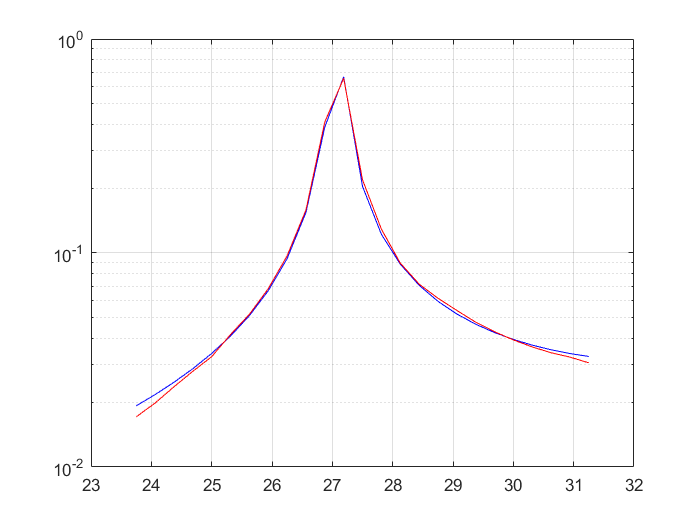

% Plotting

semilogy(freqs,abs(X_2),'b')
hold on
grid on
semilogy (freqs,abs(amps),'r')
grid on
hold off

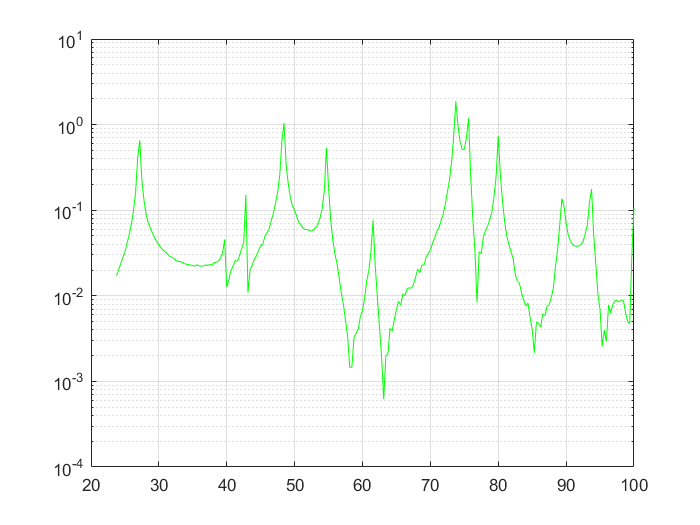

% MDOF model

freqs_2=B(61:305) ;
amps_2=A(61:305,30) ;

semilogy (freqs_2,abs(amps_2),'g')
grid on

%Creation of the K-matrix

K_2 = zeros(245,98);

omegas_2 = 2*pi*freqs_2';
omegas_2 = omegas_2/omegas_2(245)            % normalize omegas from 0 to 1

omegas_2 =     0.2375
    0.2406
    0.2437
    0.2469
    0.2500
    0.2531
    0.2562
    0.2594
    0.2625
    0.2656



for j = 1:245
    for k = 1:49
        K_2(j,k) = ((1i*omegas_2(j))^(k-1))*amps_2(j);
        K_2(j,k+49) = -(1i*omegas_2(j))^(k-1);
    end
end


% solving for theta with unit constraint

Y_2 = -K_2(:,49)             % theta_2(49) = 1

Y_2 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i



K_2(:,49) = [];              % eliminating the column we use as input

theta_2  = K_2\Y_2           % coefficients (97 because we eliminated the order 48 from den)

theta_2 =    0.0001 + 0.0000i
  -0.0000 + 0.0015i
  -0.0144 - 0.0005i
   0.0025 - 0.0748i
   0.2313 + 0.0077i
  -0.0140 + 0.4159i
  -0.3616 - 0.0122i
   0.0000 + 0.0000i
  -0.1812 - 0.0061i
   0.0000 + 0.0000i


% Model FRF

G_2 = zeros(245,97);
G_2num = zeros(245,49);
G_2den = zeros(245,49); 
Gtot = zeros(1,245);

for j = 1:245
    for k = 1:49        
        G_2num(j,k) = ((1i*omegas_2(j))^(k-1))*theta_2(k+48);         % numerators' terms
    end
end

Gtotnum = sum(G_2num,2)                                               % numerators

Gtotnum = 	1.0e+-10 *

  -0.0874 - 0.4184i
  -0.0690 - 0.3091i
  -0.0515 - 0.2105i
  -0.0353 - 0.1233i
  -0.0206 - 0.0481i
  -0.0077 + 0.0153i
   0.0033 + 0.0670i
   0.0125 + 0.1077i
   0.0200 + 0.1381i
   0.0258 + 0.1590i



for j = 1:245
    for k = 1:48      
        G_2den(j,k) = ((1i*omegas_2(j))^(k-1))*theta_2(k);            % denominators' terms
        G_2den(j,49) = ((1i*omegas_2(j))^(48))*1; 
    end
end

Gtotden = sum(G_2den,2)                                               % denominators

Gtotden = 	1.0e+-8 *

   0.2506 - 0.0043i
   0.1584 - 0.0043i
   0.0917 - 0.0040i
   0.0452 - 0.0036i
   0.0147 - 0.0031i
  -0.0037 - 0.0026i
  -0.0131 - 0.0021i
  -0.0159 - 0.0018i
  -0.0142 - 0.0015i
  -0.0098 - 0.0013i



for j = 1:245
    Gtot(j) = Gtotnum(j)/Gtotden(j);                                  % transfer functions
end

% Plotting

semilogy (freqs_2,abs(amps_2),'g') % output from sensors
hold

Current plot held


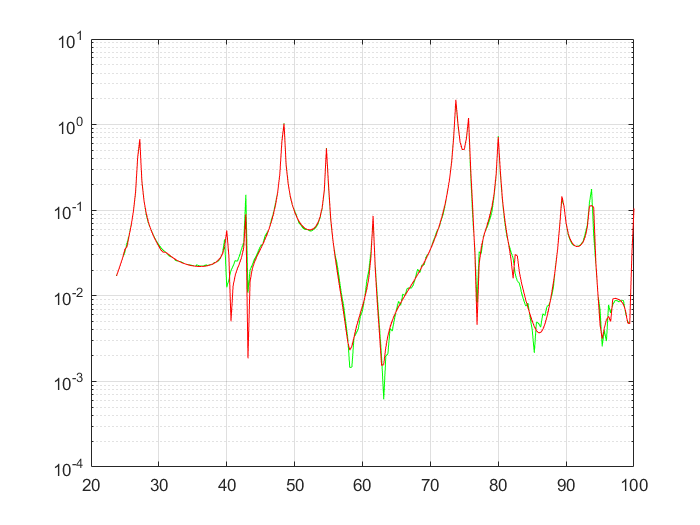

semilogy (freqs_2,abs(Gtot),'r')   % output from model (1=input)
grid on

% Estimate of poles


p_2 = [theta_2(1) theta_2(2) theta_2(3) theta_2(4)...
    theta_2(5) theta_2(6) theta_2(7) theta_2(8)...
    theta_2(9) theta_2(10) theta_2(11) theta_2(12)...
    theta_2(13) theta_2(14) theta_2(15) theta_2(16)...
    theta_2(17) theta_2(18) theta_2(19) theta_2(20)...
    theta_2(21) theta_2(22) theta_2(23) theta_2(24)...
    theta_2(25) theta_2(26) theta_2(27) theta_2(28)...
    theta_2(29) theta_2(30) theta_2(31) theta_2(32)...
    theta_2(33) theta_2(34) theta_2(35) theta_2(36)...
    theta_2(37) theta_2(38) theta_2(39) theta_2(40)...
    theta_2(41) theta_2(42) theta_2(43) theta_2(44)...
    theta_2(45) theta_2(46) theta_2(47) theta_2(48) 1]

p_2 =    0.0001 + 0.0000i  -0.0000 + 0.0015i  -0.0144 - 0.0005i   0.0025 - 0.0748i   0.2313 + 0.0077i  -0.0140 + 0.4159i  -0.3616 - 0.0122i   0.0000 + 0.0000i  -0.1812 - 0.0061i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2637 + 0.0084i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0183 - 0.6100i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.8949 - 0.0246i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0488 - 2.1217i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.4361 - 0.0693i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.5946 + 0.0588i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9235 - 0.0367i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0152 - 1.9221i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.6855 + 0.0058i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0016 - 1.8893i   1.0000 + 0.0000i



p_2 = flip(p_2)

p_2 =    1.0000 + 0.0000i   0.0016 - 1.8893i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.6855 + 0.0058i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0152 - 1.9221i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9235 - 0.0367i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.5946 + 0.0588i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.4361 - 0.0693i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0488 - 2.1217i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.8949 - 0.0246i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0183 - 0.6100i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2637 + 0.0084i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1812 - 0.0061i   0.0000 + 0.0000i  -0.3616 - 0.0122i  -0.0140 + 0.4159i   0.2313 + 0.0077i   0.0025 - 0.0748i  -0.0144 - 0.0005i  -0.0000 + 0.0015i   0.0001 + 0.0000i




lambdas_2 = roots(p_2);

fres_2 = abs(lambdas_2)/(2*pi)

fres_2 =     0.1786
    0.1786
    0.1708
    0.1708
    0.1663
    0.1663
    0.1465
    0.1560
    0.1465
    0.1560


fress = fres_2*100*6.28

fress =   112.1297
  112.1301
  107.2923
  107.2921
  104.4218
  104.4190
   92.0096
   97.9586
   92.0301
   97.9389


ksi = -(real(lambdas_2))/norm(lambdas_2)

ksi =     0.1613
   -0.1614
    0.1156
   -0.1159
    0.0639
   -0.0642
    0.0686
    0.0211
    0.0315
   -0.0214
